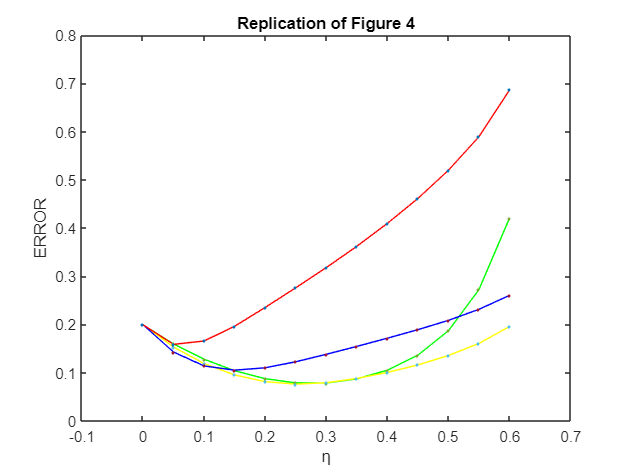

Wexact=([0:6]/6)';
Winitial=[0 0.5 0.5 0.5 0.5 0.5 1]';
lamlist=[0:0.1:1];
alist=[0:0.05:0.6];
store=zeros(11,13);
X=diag(ones(1,7));
% Update after sequence
tol=0.1;
for chooselam=1:11
    lam=lamlist(chooselam);
for choosea=1:13
    a=alist(choosea);

for set=1:100
    Wold=Winitial;
    Wnew=Wold;
      for i=1:10
         z=zeros(5,1);
         episode=training_sets(i,:,set);
         for j=1:length(episode)
             z=lam*z+X(2:6,episode(j));
             TD=Wold'*( X(:,episode(j+1))-X(:,episode(j)) ); % might be different
             Wnew(2:6)=Wnew(2:6)+0.75*a*TD*z;
             if episode(j+1)>=6.5
                 break
             elseif episode(j+1)<=1.5
                 break
             end
         end
         Wold=Wnew;
      end
RMS(set)=sqrt(mean((Wnew-Wexact).^2));
end
store(chooselam,choosea)=mean(RMS);

end

end
[0 3 8 10];
plot(alist,store(1,:),'g');
hold on
plot(alist,store(4,:),'y');
plot(alist,store(9,:),'b');
plot(alist,store(11,:),'r');
plot(alist,store(1,:),'.');
plot(alist,store(4,:),'.');
plot(alist,store(9,:),'.');
plot(alist,store(11,:),'.');
xlim([-0.1,0.7])
ylim([0,0.8])
xlabel('η')
ylabel('ERROR')
title('Replication of Figure 4')